# TUTORIAL Three-phase systems, steady state

Created by FGL, 14.02.2019 In the balanced 3-phase system of Fig. Q.7, determine the total apparent power, average power, reactive power and power factor.

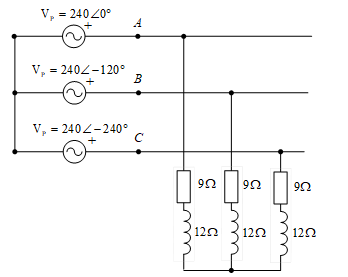

clc
clear all
fprintf(' TUTORIAL: Three-phase systems, steady state, equivalent model \n\n')

 TUTORIAL: Three-phase systems, steady state, equivalent model 



## INPUT DATA

VLN = 240 *e xp(+i*0*pi/180); % VLN: Line to neutral supply voltage in volts
ZLOAD = 9 + i * 12;           % ZL: Load impedance per phase in Ohms

## CALCULATIONS

## Ohm’s law is used to calculate the line-current (LL1):

IL1 = VLN / (ZLOAD);         % Applying Ohm's law
disp(' Line current in phase a');

 Line current in phase a


fprintf(' IL = (%5.3f + %5.3fj) A (line current) \n',real(IL1),imag(IL1))

 IL = (9.600 + -12.800j) A (line current) 


fprintf(' IL = (%5.3f < %5.3f) A  (line current)\n\n',abs(IL1),angle(IL1)*180/pi)

 IL = (16.000 < -53.130) A  (line current)



## Calculating the apparent power S = P + j Q

Single phase power and Three-phase power

% Single phase power
% S = VLN * conj(IL1);
fprintf(' S1p = (%5.3f + %5.3fj) VA (single phase)\n',real(S),imag(S))

 S1p = (2304.000 + 3072.000j) VA (single phase)


fprintf(' S1p = (%5.3f < %5.3f) VA (single phase)\n\n',abs(S),angle(S)*180/pi)

 S1p = (3840.000 < 53.130) VA (single phase)



S = 3*S;
% 3-phase power
fprintf(' S3p = (%5.3f + %5.3fj) VA (three-phase) \n',real(S),imag(S))

 S3p = (6912.000 + 9216.000j) VA (three-phase) 


fprintf(' S3p = (%5.3f < %5.3f) VA (three-phase) \n',abs(S),angle(S)*180/pi)

 S3p = (11520.000 < 53.130) VA (three-phase) 
